Geometry Model

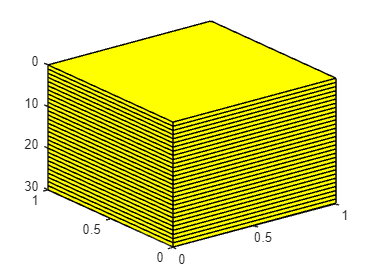

G=cartGrid([1,1,30],[1,1,30]*meter^3);
G=computeGeometry(G);
plotGrid(G);view(3);

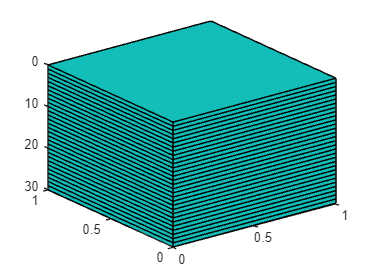

%petrophysical and other geological properties
rock=makeRock(G,0.1*darcy(),0.2);
cla,plotCellData(G,rock.perm);

Boundary Conditions

sol=initResSol(G,0.0);
bc=pside([],G,'TOP',100*barsa());

Fluid Model

hT=computeTrans(G,rock);
mrstModule add incomp
gravity reset on
fluid=initSingleFluid('mu',1*centi*poise,'rho',1014*kilogram/meter^3);
[mu,rho]=fluid.properties();

Solve

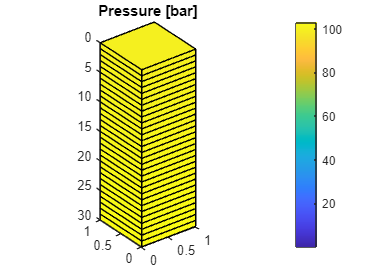

sol=incompTPFA(sol,G,hT,fluid,'bc',bc);
plotFaces(G, 1:G.faces.num, convertTo(sol.facePressure, barsa()));
set(gca, 'ZDir', 'reverse'), title('Pressure [bar]')
view(3), colorbar, set(gca,'DataAspect',[1 1 10])